# Example 2.19: Circle of Trust

Note: this script reproduces Example 2.19 (Section 2.2.6) of **Statistics for Chemical Engineers**: confidence regions for two independent Gaussian RVs. Victor Z UW-Madison, 2020 define ellipse using chi-square RV

clc; clear all; close all hidden; 
format short; 
addpath('./Support')

## Model

specify mean and covariance

mu = [0 0];
Sigma = [1 0;0 1]; % anticorrelated

## 90% confidence region (circle)

compute the 90% confidence interval ellipse

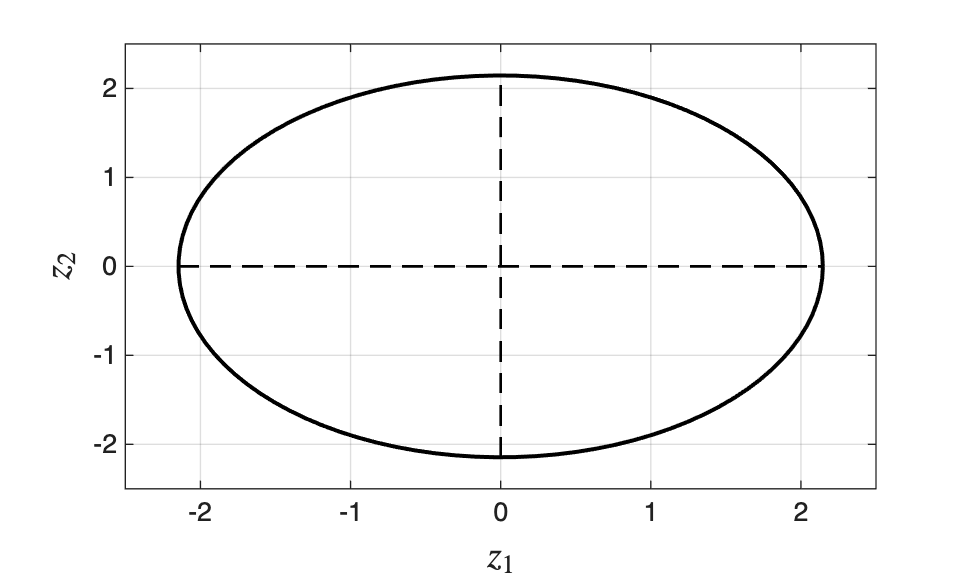

alpha = 0.9; % confidence 
n = 2; % dimension of variable
A = inv(Sigma); % inverse covariance
b = chi2inv(alpha, 2); % confidence level on 2d from chi2 distribution
[xe, ye, major, minor, bbox] = ellipse(A, b, 100, mu); % ellipse

% plot the ellipse 
figure(1); 
plot(xe,ye,'k','LineWidth',1.5) % plot ellipse
hold on;
xlabel('$z_1$','Interpreter','latex','FontSize',14); ylabel('$z_2$','Interpreter','latex','FontSize',14);
grid on

% plot 90% confidence regions
b = chi2inv(alpha, 2); 
xx=linspace(-sqrt(b),sqrt(b));
yy1=linspace(0,0);
plot(xx,yy1,'black--','LineWidth',1.0)
plot(yy1,xx,'black--','LineWidth',1.0)
axis([-2.5 2.5 -2.5 2.5])
print -depsc ch2_example_ellipse.eps

## Comparison with the individual regions

compare now with individual regions

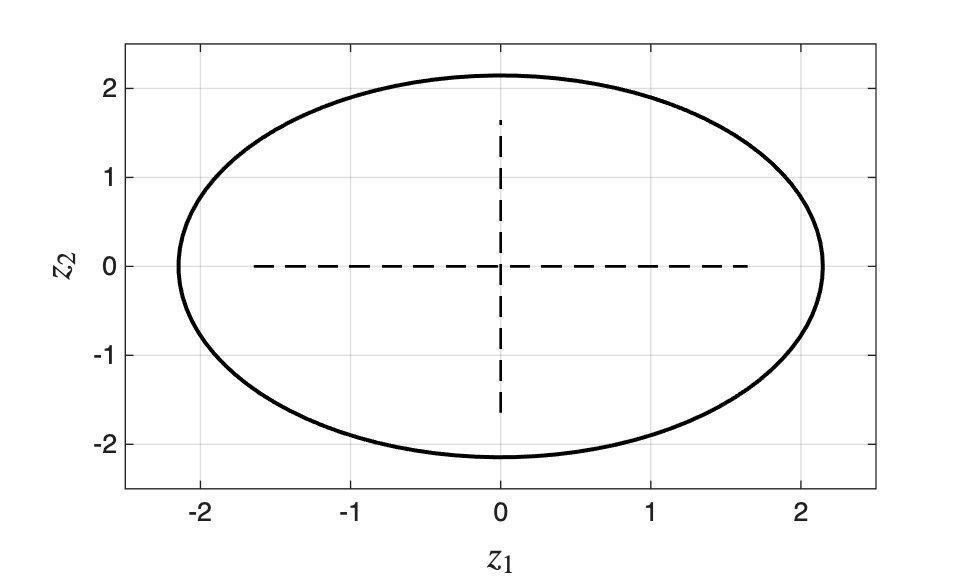

% plot the ellipse
figure(2) 
plot(xe,ye,'k','LineWidth',1.5) % plot ellipse
hold on;
xlabel('$z_1$','Interpreter','latex','FontSize',14); ylabel('$z_2$','Interpreter','latex','FontSize',14);
grid on

% plot 90% confidence regions for N(0,1),
bb = chi2inv(alpha, 1); 
xx=linspace(-sqrt(bb),sqrt(bb));
yy1=linspace(0,0);
plot(xx,yy1,'black--','LineWidth',1.0)
plot(yy1,xx,'black--','LineWidth',1.0)
axis([-2.5 2.5 -2.5 2.5])



% count the number of samples in the ellipse
rng(0)
nsample = 1000; % number of random samples
sample = mvnrnd(mu,Sigma,nsample); % collect samples
cnt = 0;
for i=1:nsample
    x = sample(i,:)-mu;
    if x*inv(Sigma)*x'<=b % count if in the confidence interval
        cnt=cnt+1;
    end        
end
fprintf('%i among %i samples in the ellipse\n',cnt,nsample); % print the result

894 among 1000 samples in the ellipse


## Note

As in the book, the 90% region for (Z1, Z2) is a circle obtained from the chi-squared RV; the individual 90% regions of Z1 and Z2 are segments along the axes of that circle.